# **Start Here:**    How does Flexibility effect a 1-dof  Robotic manipulator

In this example we're going to explore a **1-dof robotic manipulator.**  In the model will represent both the mechanical and electrical components of the system, e.g.:

- A DC motor,  A H-Bridge,  A Gear Box

- A PID position controller

But the real focus of this case study, is how we represent the Mechanical "LINK" (or arm) of the robot.  Regarding the "flexibility" of the LINK, we have 2 choices for how we could represent this:

- a **RIGID** body - the LINK is a rigid body and there is NO flexibility

- a **FLEXIBLE** body - the LINK is flexible and **can bend**

As we're about to see, the "flexibility" dynamics of the LINK become significant when as designers we make poor choices for the geometry and materials of these mechanical components.

## The 1-dof Robotic manipulator

So, the system that we're going to explore today is shown below:

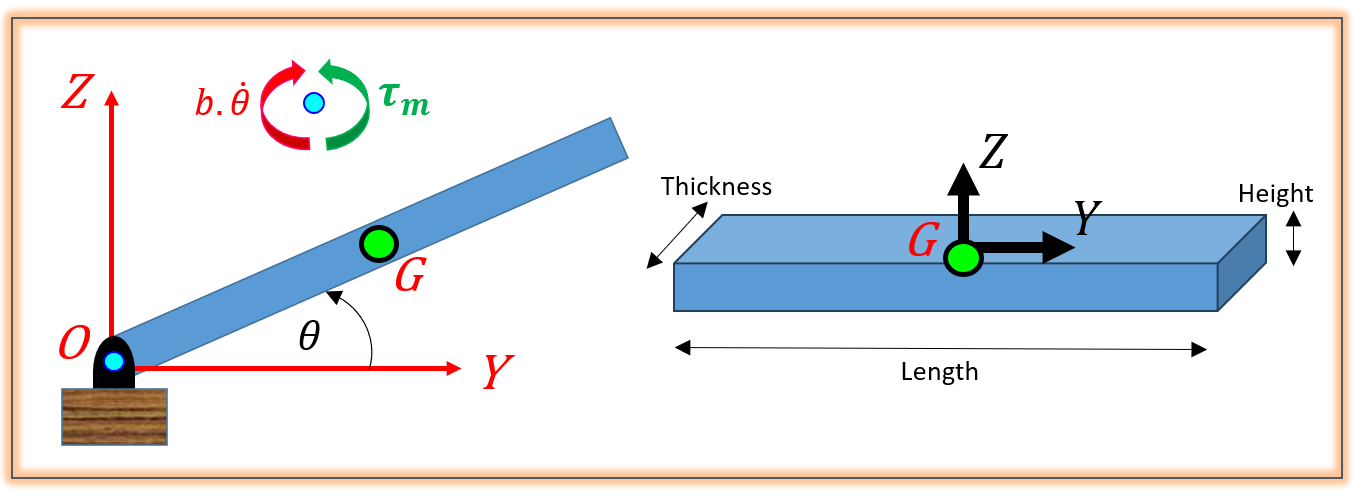

`Bradley Horton : 09-Mar-2026, bhorton@mathworks.com`

# **STEP_01:**   Model parameters

## Our ENVIRONMENT

So gravity acts in the `-Z` direction of the inertial (WORLD) frame

gravity_vec = [0,0,-9.8065]; % (m/s^2)

## Our LINK:

Specify the geometry and inertia of our robotic link

- See the class definition file  - [`bh_brick_CLS.m`](matlab: open bh_brick_CLS.m)

my_LINK_OBJ = bh_brick_CLS();

my_LINK_OBJ.Length     =  30/100;  % m
my_LINK_OBJ.Height     =  1/1000;  % m
my_LINK_OBJ.Thickness  =   8/100;  % m
my_LINK_OBJ.Mass       =  0.1875;  % kg

And some material properties

my_LINK_OBJ.E_Gpa       = 70; %200;   % Gpa
my_LINK_OBJ.Poisson_rat = 0.33;  %(-)

So what have we got ?

my_LINK_OBJ

my_LINK_OBJ =   bh_brick_CLS with properties:

           Length: 0.3000
           Height: 1.0000e-03
        Thickness: 0.0800
    LHT_body_axes: "YZX"
             Mass: 0.1875
            E_Gpa: 70
      Poisson_rat: 0.3300
          vec_XYZ: [0.0800 0.3000 1.0000e-03]
          density: 7.8125e+03


## Define some damping at the joint:

We will assume that the rotational joint experiences viscous damping,The damping torque is a function of the relative joint velocity, e.g.:  $\tau_{\mathrm{DAMP}} =b_1 \ldotp {\dot{\theta} }_1$

- See the class definition file  - [`bh_joint_CLS.m`](matlab: open bh_joint_CLS.m)

my_joint_1_OBJ         = bh_joint_CLS();
my_joint_1_OBJ.Damp    = 0.01;  % (N.m/(rad/sec));

## The INITIAL Conditions:

Here are the INITIAL conditions for the robot arm

my_joint_1_OBJ.theta     =  0*pi/180; % (rad)
my_joint_1_OBJ.theta_dot =  0*pi/180; % (rad/sec) 

So what have we got ?

my_joint_1_OBJ

my_joint_1_OBJ =   bh_joint_CLS with properties:

        theta: 0
    theta_dot: 0
         Damp: 0.0100


# **STEP_02:**   Rigid vs Flexible Simulation

Now let's open a Simulink model that compares the 2 different flexibility approaches for representing the robot LINK. As a reference, the 2 **Simscape Multibody block**s that we're using for the the 2 different flexibility approaches , are given below:

- the **RIGID body** approach - see [**HERE**](https://au.mathworks.com/help/releases/R2026a/sm/ref/bricksolid.html)

- the **FLEXIBLE body** approach - see [**HERE**](https://au.mathworks.com/help/releases/R2026a/sm/ref/flexiblerectangularbeam.html)

When you open the Simulink file, you'll see we have a identical Electrical components and controllers acting on each robot configuration - the only difference is how we represent the Mechanical LINK (arm) of the robot

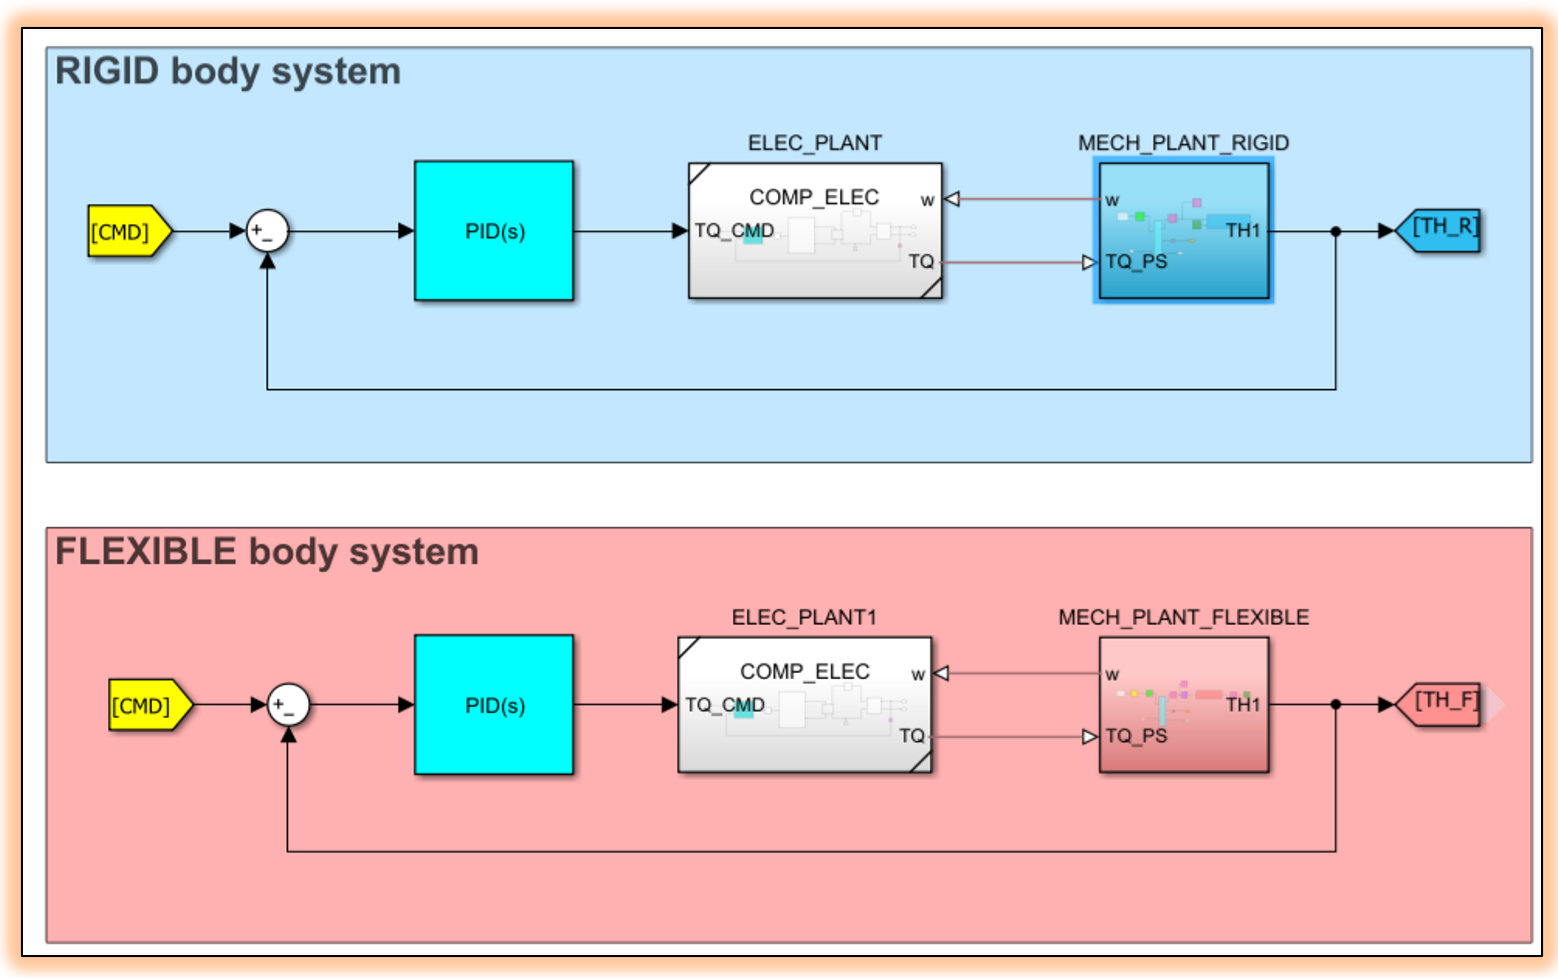

OK - So let's open the Simulink model

THE_MODEL_NAME = "bh_explore_1dof_ROBOT_rigid_vs_flexible"

THE_MODEL_NAME = "bh_explore_1dof_ROBOT_rigid_vs_flexible"

open_system(THE_MODEL_NAME)

Turn off the Mechanics Explorer initially (there will be a button in the model where we can turn it on)

set_param(THE_MODEL_NAME,"SimMechanicsOpenEditorOnUpdate", 'off')